% Pulse Width Modulation
clc;
clear;
fs=input("Enter frequency of Sawtooth ");
fm=input("Enter frequency of Message signal ");
A=input("Enter amplitude of Sawtooth ");
t=0:0.0001:1; % upto 10000 samples

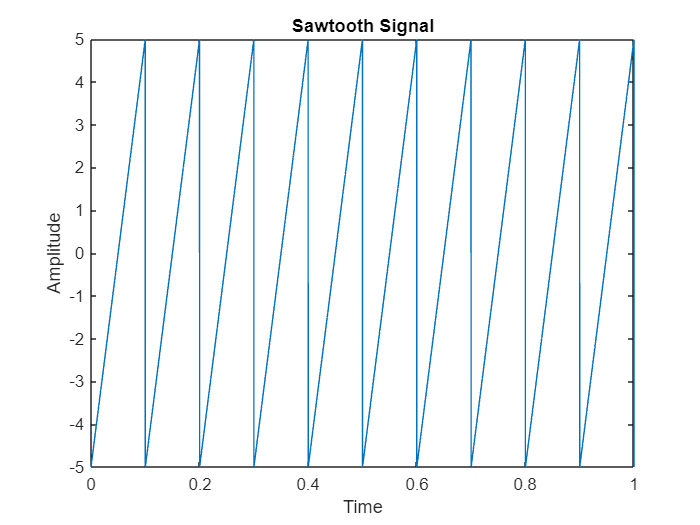

% Sawtooth Signal
st=A*sawtooth(2*pi*fs*t);
plot(t,st);
xlabel("Time");
ylabel("Amplitude");
title("Sawtooth Signal");

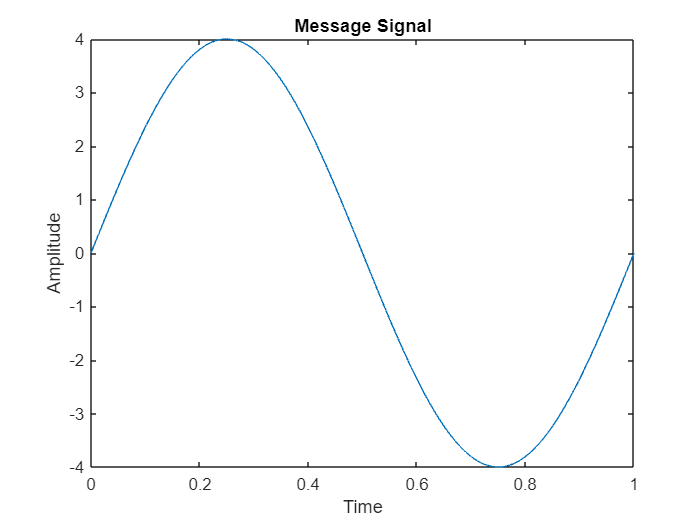

% Message Signal
% Amplitude of message signal shoulde be less than amplitude of Sawtooth Signal
mt=0.80*A*sin(2*pi*fm*t);
plot(t,mt);
xlabel("Time");
ylabel("Amplitude");
title("Message Signal");

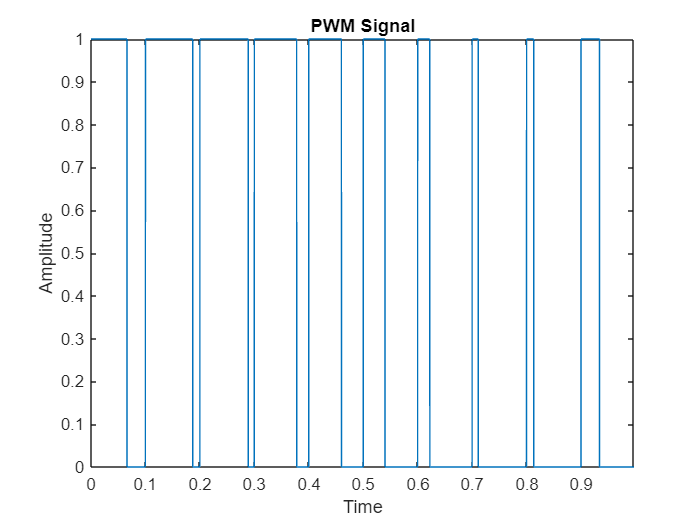

% PWM signal
pwm=zeros(1,length(st));
for i=1:length(st)
    if mt(i)>=st(i)
        pwm(i)=1;
    else
        pwm(i)=0;
    end
end
plot(t,pwm);
xlabel("Time");
ylabel("Amplitude");
title("PWM Signal");